#### **Cuantificación uniforme. Tarea 1**

- Para x=-2:0.001:2 , xsc=1 y n=3

- Representad la salida y el error de cuantificación de los dos cuantificadores respecto a la entrada x. 

- Indicad la zona de error granular y la zona de error de sobrecarga.

- Ajustad adecuadamente los límites de las gráficas (funciones axis, xlim, ylim,. . . ).

x=-2:0.001:2, xsc = 1, n=3

x =    -2.0000   -1.9990   -1.9980   -1.9970   -1.9960   -1.9950   -1.9940   -1.9930   -1.9920   -1.9910   -1.9900   -1.9890   -1.9880   -1.9870   -1.9860   -1.9850   -1.9840   -1.9830   -1.9820   -1.9810   -1.9800   -1.9790   -1.9780   -1.9770   -1.9760   -1.9750   -1.9740   -1.9730   -1.9720   -1.9710   -1.9700   -1.9690   -1.9680   -1.9670   -1.9660   -1.9650   -1.9640   -1.9630   -1.9620   -1.9610   -1.9600   -1.9590   -1.9580   -1.9570   -1.9560   -1.9550   -1.9540   -1.9530   -1.9520   -1.9510


xsc = 1

n = 3

[y, pe, pesc, peg] = qmidriser(x, xsc, n)

y =    -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750   -0.8750


pe =    -1.1250   -1.1240   -1.1230   -1.1220   -1.1210   -1.1200   -1.1190   -1.1180   -1.1170   -1.1160   -1.1150   -1.1140   -1.1130   -1.1120   -1.1110   -1.1100   -1.1090   -1.1080   -1.1070   -1.1060   -1.1050   -1.1040   -1.1030   -1.1020   -1.1010   -1.1000   -1.0990   -1.0980   -1.0970   -1.0960   -1.0950   -1.0940   -1.0930   -1.0920   -1.0910   -1.0900   -1.0890   -1.0880   -1.0870   -1.0860   -1.0850   -1.0840   -1.0830   -1.0820   -1.0810   -1.0800   -1.0790   -1.0780   -1.0770   -1.0760


pesc = 0.2398

peg = 0.2372

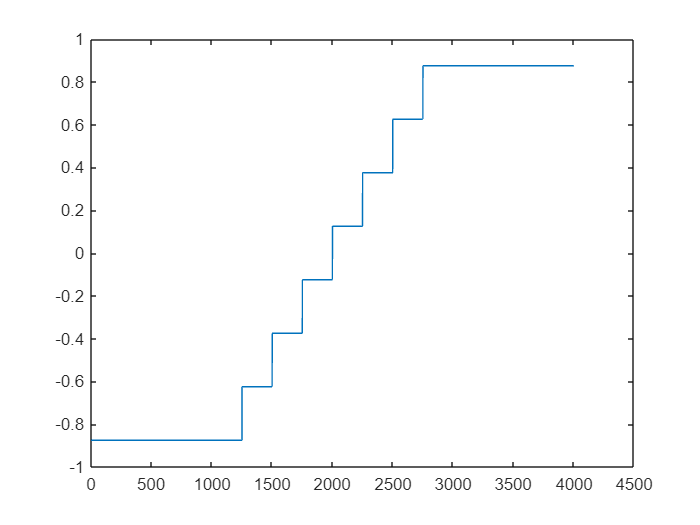


plot(y); %Salida del midriser, con 8 escalones

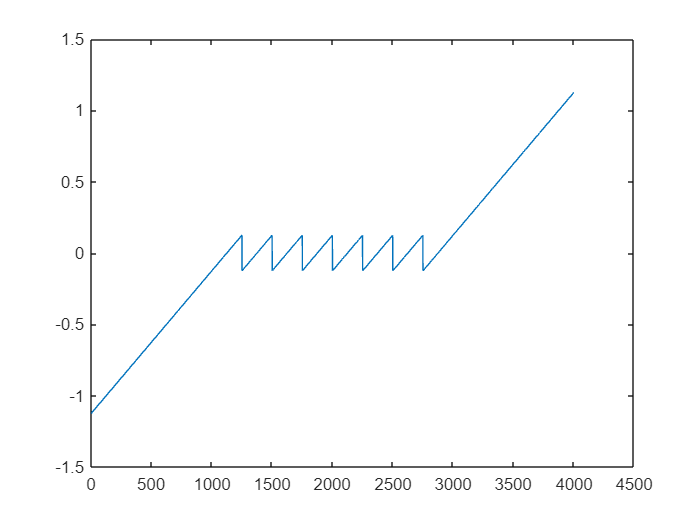

plot(pe); %Error del midriser, con el error granular entre las 1000 y 3000 muestras y el de sobrecarga fuera de esos límites


[y, pe, pesc, peg] = qmidtread(x, xsc, n)

y =    -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571   -0.8571


pe =    -1.1429   -1.1419   -1.1409   -1.1399   -1.1389   -1.1379   -1.1369   -1.1359   -1.1349   -1.1339   -1.1329   -1.1319   -1.1309   -1.1299   -1.1289   -1.1279   -1.1269   -1.1259   -1.1249   -1.1239   -1.1229   -1.1219   -1.1209   -1.1199   -1.1189   -1.1179   -1.1169   -1.1159   -1.1149   -1.1139   -1.1129   -1.1119   -1.1109   -1.1099   -1.1089   -1.1079   -1.1069   -1.1059   -1.1049   -1.1039   -1.1029   -1.1019   -1.1009   -1.0999   -1.0989   -1.0979   -1.0969   -1.0959   -1.0949   -1.0939


pesc = 0.2520

peg = 0.2486

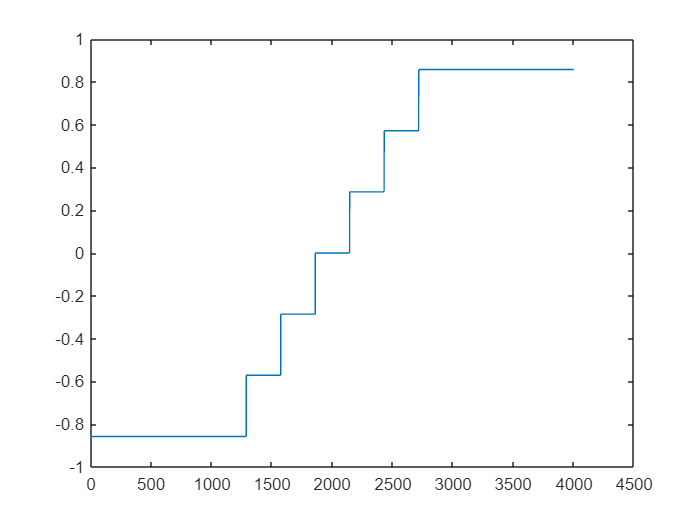


plot(y); %Salida del cuantificador midtread, se observa un escalón menos

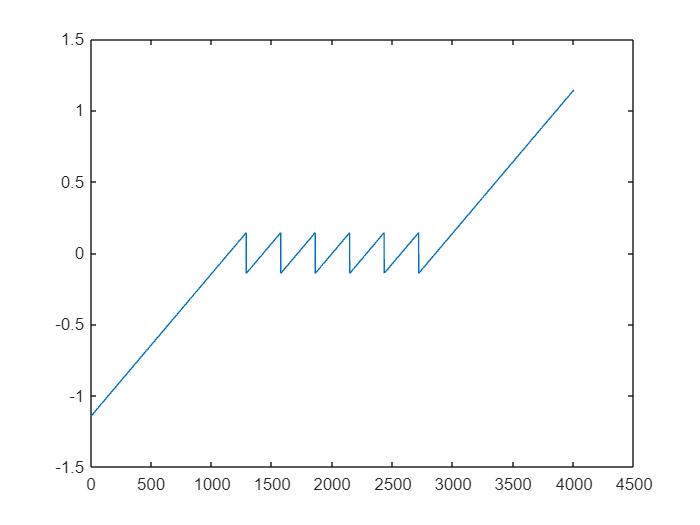

plot(pe); %Error del midtread, con el error granular entre las 1000 y 3000 muestras y el de sobrecarga fuera de esos límites

- Archivos Afonso_8kHz.wav y Gala_8kHz.wav, muestreados a 8 kHz y 16 bits (128 kbps). 

- Se pueden cargar con la función audioread() 

- Se pueden escuchar con sound() o soundsc() 

[Afonso, fsafonso] = audioread('Afonso_8khz.wav') %Se guardan ambas señales y sus frecuencias de muestreo en variables diferentes

Afonso =          0
   -0.0001
   -0.0002
   -0.0002
    0.0000
    0.0002
   -0.0001
   -0.0002
   -0.0002
    0.0002


fsafonso = 8000

[Gala, fsgala] = audioread('Gala_8khz.wav')

Gala =     0.0000
    0.0000
    0.0000
    0.0000
         0
         0
         0
         0
   -0.0000
   -0.0000


fsgala = 8000

sound(Afonso, fsafonso); %Escuchar la primera señal
sound(Gala, fsgala); %Escuchar la segunda señal

- Cuantificación a 8, 4 y 2 bits, con qmidriser() y qmidtread(), xsc=1. 

- Escuchad y comentad los resultados. (Afonso y Gala) 

- Representad el error de cuantificación (Gala) y comentad los resultados.

%Cuantificador de midtread para la señal Afonso
[afonso8, pe, pesc, peg] = qmidtread(Afonso, 1, 8)

afonso8 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =          0
   -0.0001
   -0.0002
   -0.0002
    0.0000
    0.0002
   -0.0001
   -0.0002
   -0.0002
    0.0002


pesc = 4.2410e-06

peg = 0

sound(afonso8, fsafonso)
[afonso4, pe, pesc, peg] = qmidtread(Afonso, 1, 4)

afonso4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =          0
   -0.0001
   -0.0002
   -0.0002
    0.0000
    0.0002
   -0.0001
   -0.0002
   -0.0002
    0.0002


pesc = 9.7795e-04

peg = 0

sound(afonso4, fsafonso)
[afonso2, pe, pesc, peg] = qmidtread(Afonso, 1, 2)

afonso2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =          0
   -0.0001
   -0.0002
   -0.0002
    0.0000
    0.0002
   -0.0001
   -0.0002
   -0.0002
    0.0002


pesc = 0.0102

peg = 0

sound(afonso2, fsafonso)
%Cuantificador de midriser para la señal Afonso
[afonso8, pe, pesc, peg] = qmidriser(Afonso, 1, 8)

afonso8 =          0
   -0.0039
   -0.0039
   -0.0039
    0.0039
    0.0039
   -0.0039
   -0.0039
   -0.0039
    0.0039


pe =          0
    0.0038
    0.0037
    0.0037
   -0.0039
   -0.0037
    0.0038
    0.0037
    0.0038
   -0.0037


pesc = 6.1491e-06

peg = 0

sound(afonso8, fsafonso)
[afonso4, pe, pesc, peg] = qmidriser(Afonso, 1, 4)

afonso4 =          0
   -0.0625
   -0.0625
   -0.0625
    0.0625
    0.0625
   -0.0625
   -0.0625
   -0.0625
    0.0625


pe =          0
    0.0624
    0.0623
    0.0623
   -0.0625
   -0.0623
    0.0624
    0.0623
    0.0623
   -0.0623


pesc = 0.0019

peg = 0

sound(afonso4, fsafonso)
[afonso2, pe, pesc, peg] = qmidriser(Afonso, 1, 2)

afonso2 =          0
   -0.2500
   -0.2500
   -0.2500
    0.2500
    0.2500
   -0.2500
   -0.2500
   -0.2500
    0.2500


pe =          0
    0.2499
    0.2498
    0.2498
   -0.2500
   -0.2498
    0.2499
    0.2498
    0.2498
   -0.2498


pesc = 0.0399

peg = 0

sound(afonso2, fsafonso)
%Cuantificador de midtread para la señal Gala
[gala8, pe, pesc, peg] = qmidtread(Gala, 1, 8)

gala8 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =     0.0000
    0.0000
    0.0000
    0.0000
         0
         0
         0
         0
   -0.0000
   -0.0000


pesc = 4.3027e-06

peg = 0

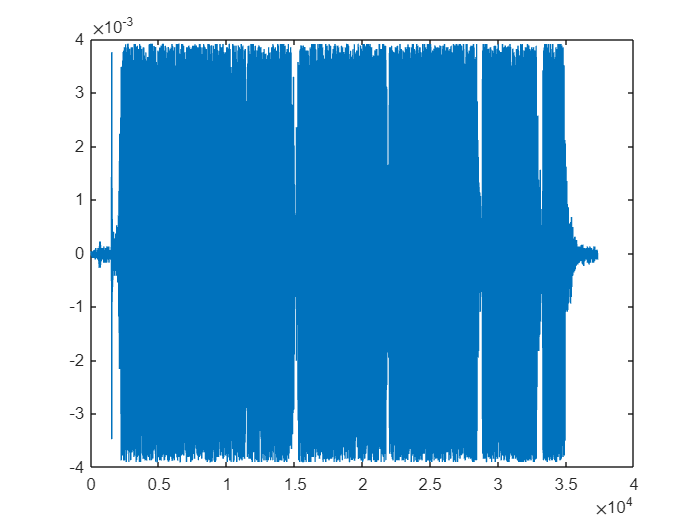

sound(gala8, fsgala)
plot(pe);

[gala4, pe, pesc, peg] = qmidtread(Gala, 1, 4)

gala4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =     0.0000
    0.0000
    0.0000
    0.0000
         0
         0
         0
         0
   -0.0000
   -0.0000


pesc = 8.3025e-04

peg = 0

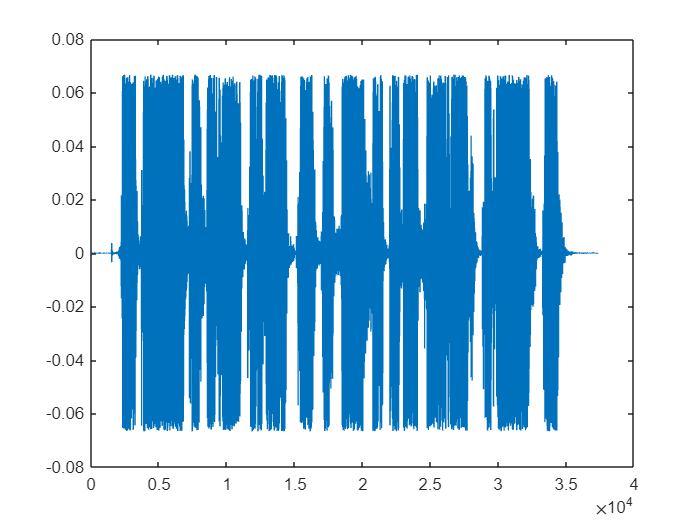

sound(gala4, fsgala)
plot(pe);

[gala2, pe, pesc, peg] = qmidtread(Gala, 1, 2)

gala2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =     0.0000
    0.0000
    0.0000
    0.0000
         0
         0
         0
         0
   -0.0000
   -0.0000


pesc = 0.0089

peg = 0

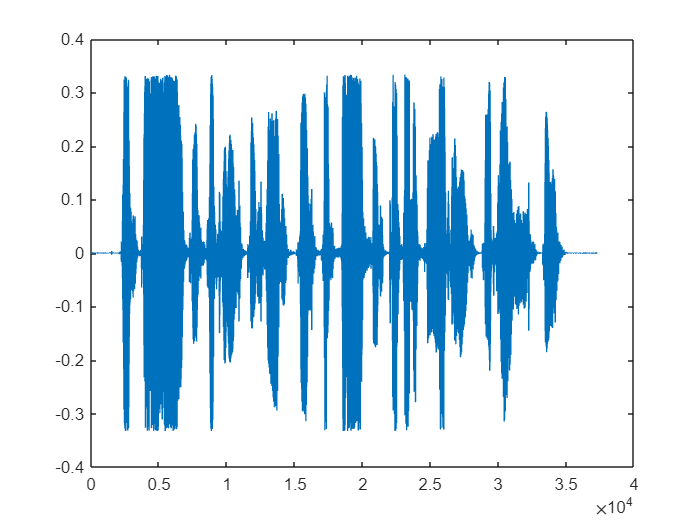

sound(gala2, fsgala)
plot(pe);

%Cuantificador de midriser para la señal Gala
[gala8, pe, pesc, peg] = qmidriser(Gala, 1, 8)

gala8 =     0.0039
    0.0039
    0.0039
    0.0039
         0
         0
         0
         0
   -0.0039
   -0.0039


pe =    -0.0039
   -0.0039
   -0.0039
   -0.0039
         0
         0
         0
         0
    0.0039
    0.0039


pesc = 6.0613e-06

peg = 0

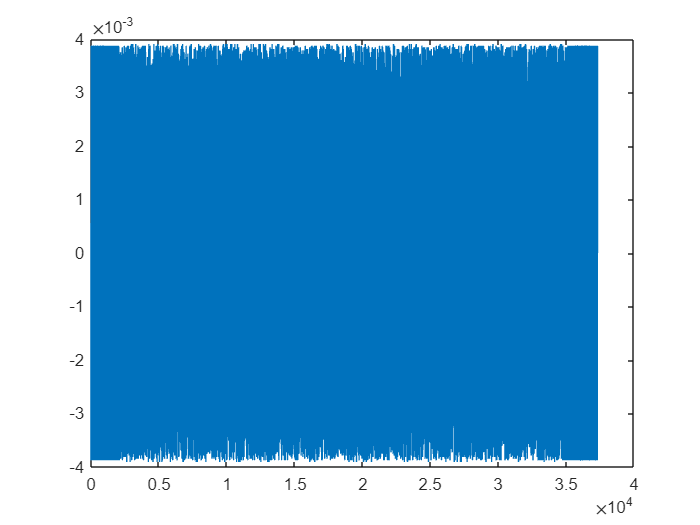

sound(gala8, fsgala)
plot(pe);

[gala4, pe, pesc, peg] = qmidriser(Gala, 1, 4)

gala4 =     0.0625
    0.0625
    0.0625
    0.0625
         0
         0
         0
         0
   -0.0625
   -0.0625


pe =    -0.0625
   -0.0625
   -0.0625
   -0.0625
         0
         0
         0
         0
    0.0625
    0.0625


pesc = 0.0021

peg = 0

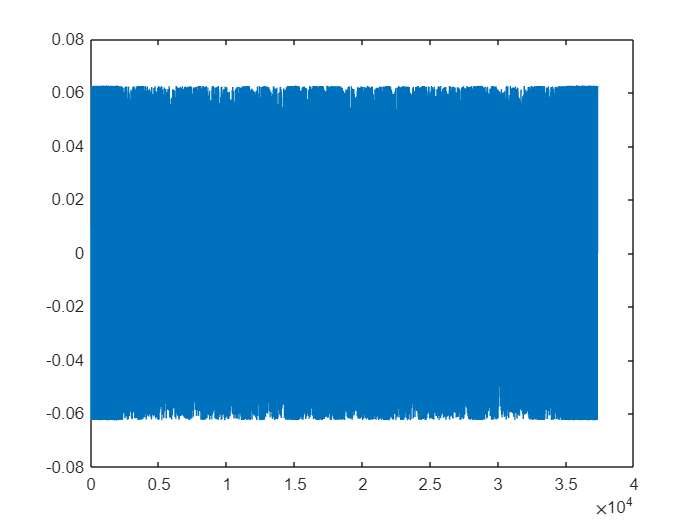

sound(gala4, fsgala)
plot(pe);

[gala2, pe, pesc, peg] = qmidriser(Gala, 1, 2)

gala2 =     0.2500
    0.2500
    0.2500
    0.2500
         0
         0
         0
         0
   -0.2500
   -0.2500


pe =    -0.2500
   -0.2500
   -0.2500
   -0.2500
         0
         0
         0
         0
    0.2500
    0.2500


pesc = 0.0429

peg = 0

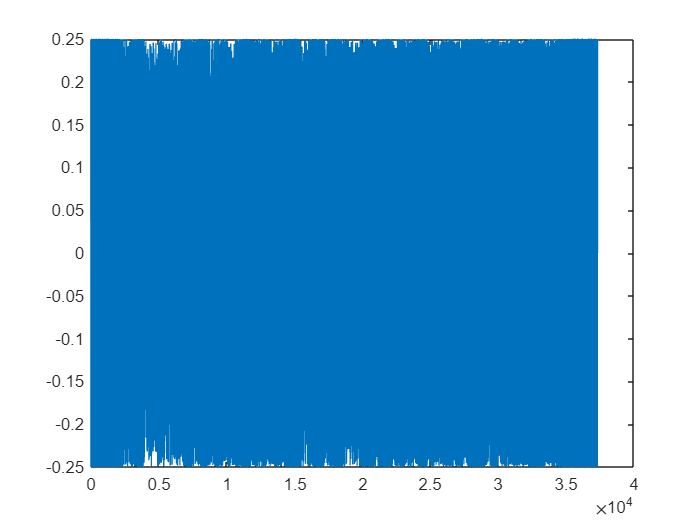

sound(gala2, fsgala)
plot(pe);

- Repetir para 8 bits, xsc=0.5 y xsc=0.3, con ambos cuantificadores.

-  Representad el error de cuantificación (Gala). Comentad los resultados.

[gala8, pe, pesc, peg] = qmidriser(Gala, 0.5, 8)

gala8 =     0.0020
    0.0020
    0.0020
    0.0020
         0
         0
         0
         0
   -0.0020
   -0.0020


pe =    -0.0019
   -0.0019
   -0.0019
   -0.0019
         0
         0
         0
         0
    0.0019
    0.0019


pesc = 1.9908e-06

peg = 5.4304e-07

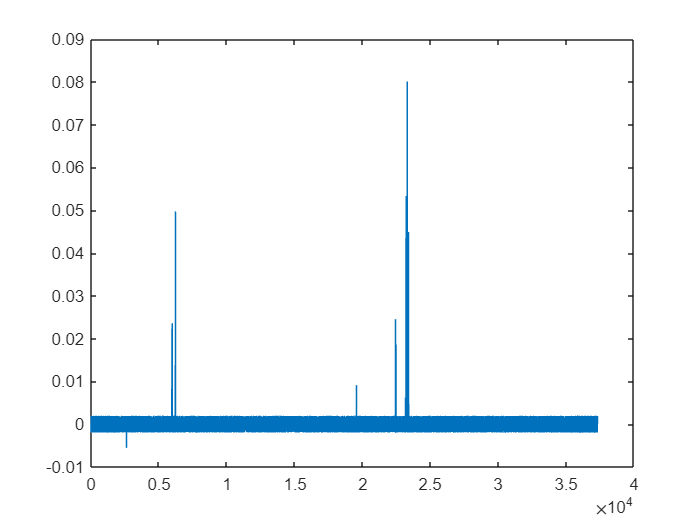

plot(pe)

[gala8, pe, pesc, peg] = qmidriser(Gala, 0.3, 8)

gala8 =     0.0012
    0.0012
    0.0012
    0.0012
         0
         0
         0
         0
   -0.0012
   -0.0012


pe =    -0.0011
   -0.0011
   -0.0011
   -0.0011
         0
         0
         0
         0
    0.0011
    0.0011


pesc = 2.5747e-04

peg = 2.5697e-04

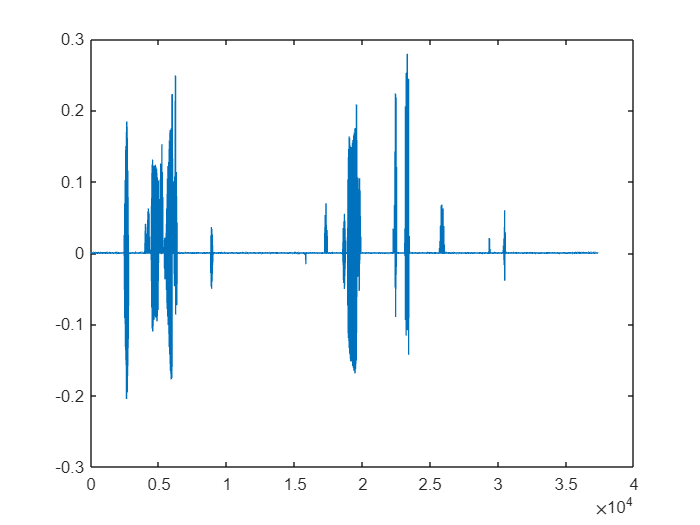

plot(pe)

[gala8, pe, pesc, peg] = qmidtread(Gala, 0.3, 8)

gala8 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =     0.0000
    0.0000
    0.0000
    0.0000
         0
         0
         0
         0
   -0.0000
   -0.0000


pesc = 2.5738e-04

peg = 2.5699e-04

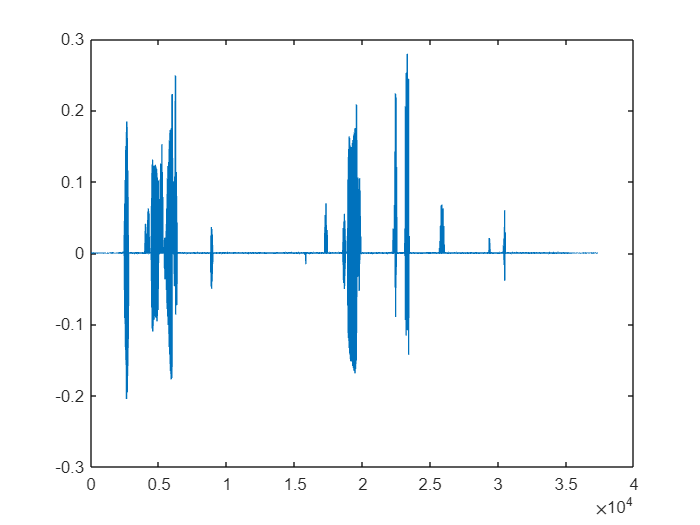

plot(pe)

[gala8, pe, pesc, peg] = qmidtread(Gala, 0.5, 8)

gala8 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pe =     0.0000
    0.0000
    0.0000
    0.0000
         0
         0
         0
         0
   -0.0000
   -0.0000


pesc = 1.6641e-06

peg = 5.4324e-07

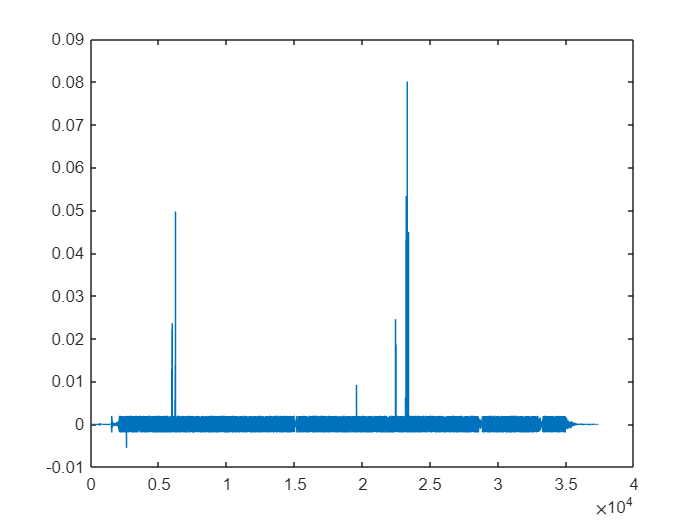

plot(pe)

%Al variar el valor de sobrecarga se observan grandes diferencias, sobre
%todo, con respecto a los cuantificadores con valor de sobrecarga 1